% Loading Data
load starData

% Calculating the speed of all stars
[sHa,idx] = min(spectra(:,:));
lambdaHa = lambda(idx);
z = lambdaHa/656.28 - 1;
speed = z*299792.458

speed =   -36.5445
 -100.4973
  -36.5445
   27.4083
   27.4083
  155.3139
 -228.4029


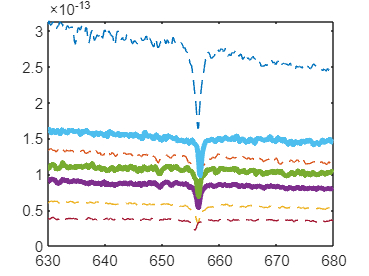

% plot the spectra of all seven stars using different line properties for redshifted and blueshifted spectra.
% If speed(v) is less than or equal to 0, create a plot of s against lambda using a dashed line (--).
% If speed(v) is greater than 0, create a plot of s against lambda using a line width of 3.
for v = 1:7
    s = spectra(:,v);
    if speed(v) <= 0
        plot(lambda,s,"--")
    else
        plot(lambda,s,"-",LineWidth=3)
    end
    hold on
end
hold off

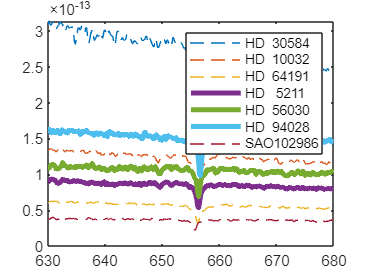

% Adding Legend and Adjusting

legend(starnames)